% OBTENCAO DAS FUNCOES DE TRANSFERENCIA PARA ANALISE DO GANHO

% G(s) = (C*[S*I-A]^(-1))*B + D

%1º forma:
%syms s 
%G = inv(s*I-A)*B

%2º forma:
% [n,d] = ss2tf(A,B,I,B*0,1ou2)


I = eye(3);

[n1,d1] = ss2tf(A,B,I,B*0,1)

n1 = 	1.0e+10 *

         0    0.0000    0.0009    2.2949
         0         0   -0.0012   -0.0001
         0         0         0   -0.6090


d1 = 	1.0e+09 *

    0.0000    0.0000    0.0067    3.6722



[n2,d2] = ss2tf(A,B,I,B*0,2)

n2 = 	1.0e+09 *

         0         0    0.0115    0.0013
         0    0.0000    0.0095    0.0005
         0         0    0.0041    4.9967


d2 = 	1.0e+09 *

    0.0000    0.0000    0.0067    3.6722



% Funções de transferencia
H11 = tf(n1(1,:),d1);
H21 = tf(n1(2,:),d1);
H31 = tf(n1(3,:),d1);
H12 = tf(n2(1,:),d2);
H22 = tf(n2(2,:),d2);
H32 = tf(n2(3,:),d2);

% Determinação de Ks para obter kp e ki
% kp = k*k1
% ki = k*k2

k1 = 1;
k2 = 1.5;

numM = [k1 k2];
denM = [1 0];
M = tf(numM,denM) 

M =
 
  s + 1.5
  -------
     s
 
Continuous-time transfer function.




G1 = M*H11

G1 =
 
                                  
  7692 s^3 + 9.479e06 s^2         
                                  
           + 2.296e10 s + 3.442e10
                                  
  --------------------------------
                                  
  s^4 + 2462 s^3 + 6.748e06 s^2   
                                  
                      + 3.672e09 s
                                  
 
Continuous-time transfer function.




k = 0.278 % Obtido pelo rotlocus

k = 0.2780


kp = k * k1;
ki = k * k2;

numD = [kp ki];
denD = [1 0];
D1=tf(numD,denD);

% Determinação de Ks para obter kp e ki
% kp = k*k1
% ki = k*k2

k12 = 2;
k22 = 1;

numM2 = [k12 k22];
denM2 = [1 0];
M2 = tf(numM2,denM2)

M2 =
 
  2 s + 1
  -------
     s
 
Continuous-time transfer function.




G2 = M2*H22 % Crime, mudança da planta com K como controlador

G2 =
 
                                  
  1.538e04 s^3 + 1.894e07 s^2     
                                  
            + 1.052e07 s + 5.26e05
                                  
  --------------------------------
                                  
  s^4 + 2462 s^3 + 6.748e06 s^2   
                                  
                      + 3.672e09 s
                                  
 
Continuous-time transfer function.



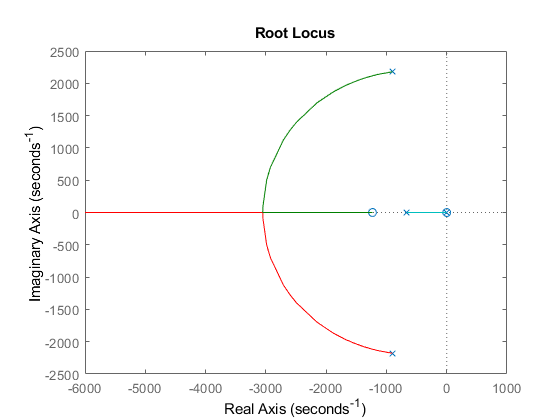

rlocus(G2)


k2 = 0.262; % Obtido pelo rootlocus

kp2 = k2 * k12;
ki2 = k2 * k22;

% (kp*S + ki)/S

numD2 = [kp2 ki2];
denD2 = [1 0];
D2=tf(numD2,denD2); % Função de transferencia do controlador, sem o crime



% J*wponto + b*w = Tal
% J*S*W(S) + b*W(S) = T(S)
% W(S)/T(S) = 1/(J*S+b)

numH3 = [0 1];
denH3 = [J b];
H3 = tf(numH3,denH3)

H3 =
 
          1
  -----------------
  0.00018 s + 1e-05
 
Continuous-time transfer function.




% Determinação de Ks para obter kp e ki
% kp = k*k1
% ki = k*k2

k13 = 1;
k23 = 2;

numM3 = [k13 k23];
denM3 = [1 0];
M3 = tf(numM3,denM3) 

M3 =
 
  s + 2
  -----
    s
 
Continuous-time transfer function.



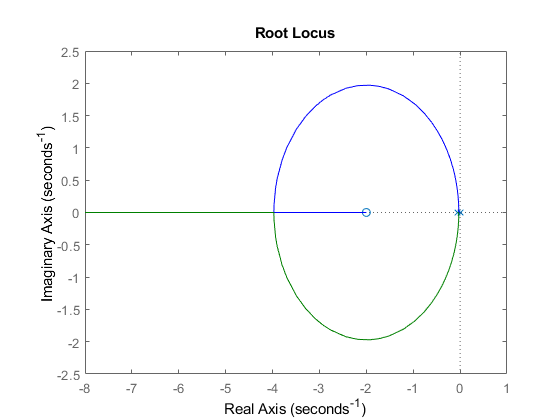


G3 = H3*M3; % Crime para achar o K
rlocus(G3)


% k = 0.0014 % Obtido pelo rootlocus

k3=0.00135

k3 = 0.0014

kp3 = k3 * k13;
ki3 = k3 * k23;

numD3 = [kp3 ki3];
denD3 = [1 0];
D3=tf(numD3,denD3) % FT do controlador, sem crime

D3 =
 
  0.00135 s + 0.0027
  ------------------
          s
 
Continuous-time transfer function.

